# Actividad #6

- Nombre:

- Fecha:

- Reposiroty: [https://github.com/vasanza/SSE](https://github.com/vasanza/SSE)

- Refrence: [https://github.com/vasanza/Matlab_Code/tree/main](https://github.com/vasanza/Matlab_Code/tree/main)

Objetivos:

- Guardar datos en formato csv

# **Primero hacer la copia en el respaldo**

%Configuracion de carpeta ./src para librerias
addpath(genpath('./src'));

% Definir rutas
miRespaldo = 'C:\Users\victo\Desktop\SSE_vic';  %<========
repositorio = 'C:\Users\victo\Desktop\SSE\2025';%<========

if true
    % repositorio -> respaldo
    git_sse(miRespaldo)
else
    % Mombre de la carpeta de la Actividad en el repositorio
    nombreCarpeta = string(split(cd, filesep));
    nombreCarpeta = nombreCarpeta(end) % Nombre de la carpeta
    % Regresar al repositorio
    cd(fullfile(repositorio,nombreCarpeta))

  --- SEÑAL SENOIDAL ---
 function [y] = senal_senoidal(frecuencia,amplitud,fase,tiempo,fs)
 
  Parámetros:
  f = 10;         % Frecuencia en Hz
  A = 1;          % Amplitud
  fase1 = 0; fase2 = 10;        % Fase
  T = 1;          % Duración en segundos
  fs = 1000;      % Frecuencia de muestreo en Hz



end

# **Ejecutar esto en el respaldo**

## **Paso 1: Borrar variables en el workspace y limpiar cmd**

clear % Borrar variables en el workspace y libera memoria RAM
clc % Limpia el Command Window

## **Paso 2: Crear un codigo basico**

% Parámetros
f = 10;         % Frecuencia de la señal en Hz
A1 = 3;          % Amplitud1
A2 = 16;          % Amplitud1
fase1 = 0;      % Fase1
fase2 = 10;     % Fase2
T = 2.5;          % Duración en segundos
fsmin = f*2;    % Frecuencia de muestreo minima (Nyquist-Shannon)
fs = 620;      % Frecuencia de muestreo en Hz

Documentacion de la senal senoidal

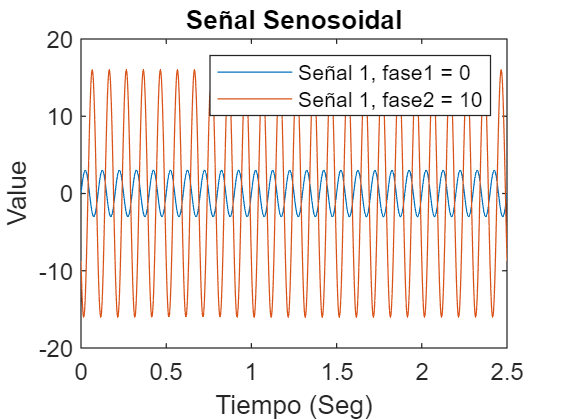

help senal_senoidal

% Usamos la funcion: senal_senoidal(frecuencia,amplitud,fase,tiempo,fs)
y1 = senal_senoidal(f,A1,fase1,T,fs);
y2 = senal_senoidal(f,A2,fase2,T,fs);

dataset =          0         0   -8.7043   -8.7043   -8.7043
    0.0016    0.3035  -10.0179   -9.7144  -10.0179
    0.0032    0.6039  -11.2286  -10.6247  -11.2286
    0.0048    0.8981  -12.3241  -11.4261  -12.3241
    0.0065    1.1831  -13.2932  -12.1101  -13.2932
    0.0081    1.4559  -14.1259  -12.6700  -14.1259
    0.0097    1.7138  -14.8136  -13.0998  -14.8136
    0.0113    1.9541  -15.3493  -13.3951  -15.3493
    0.0129    2.1744  -15.7274  -13.5531  -15.7274
    0.0145    2.3723  -15.9443  -13.5719  -15.9443


## **Paso 4: Mostrar resultados con plot**

t = 0:1/fs:T;
figure
plot(t,y1) %Señal 1
hold on
plot(t,y2) %Señal 2
title("Señal Senosoidal")
xlabel("Tiempo (Seg)")
ylabel("Value")
legend("Señal 1, fase1 = 0", "Señal 1, fase2 = 10")

## **Paso 5: crear dataset**

dataset = [t' y1' y2' (y1 + y2)']

## Paso 6: Guardar los carchivos VSC en el computador

filename = 'Datos4.csv';
fSave_file(filename,dataset)